# Display Robustness Outcomes

## Sparsity tuning affect on density and controllability

%Density vs. rho for each patient
clear d;

betas= [0, .01, .05, .1 ];
gammas= [ 0, .1, .25, .5, .75];

betaStr=replace(string(betas), '.', '_');
gammaStr=replace(string(gammas), '.', '_');

for g=1:length(gammas)
    for i_pt=1:length(Network)
        load(sprintf('Data/Robustness/Network_%s.mat',gammaStr{g}))
        pcm= Network(i_pt).pcm;
        [N,~,T]=size(pcm);
        % Get density, ignore zeros. 
        d(g,i_pt)=(sum(pcm(:)~=0))./(numel(pcm)-N*T);
        avg_rho(g,i_pt)=mean(Network(i_pt).rhos);
        std_rho(g,i_pt)=std(Network(i_pt).rhos);
    end
end



figure(3); clf; hold on
plot(gammas, d(:,1:7))
xlabel('gamma'); ylabel('density')
xticks(gammas);
title('Density plot')

figure(2); clf; hold on
for z=1:7
    errorbar(gammas, avg_rho(:,z), std_rho(:,z));
end
xlabel('gamma'); ylabel('rho values')
xticks(gammas);
title('avg. rho')

% How does sparsity affect average controllability values?


## Contiguity Tuning (beta)

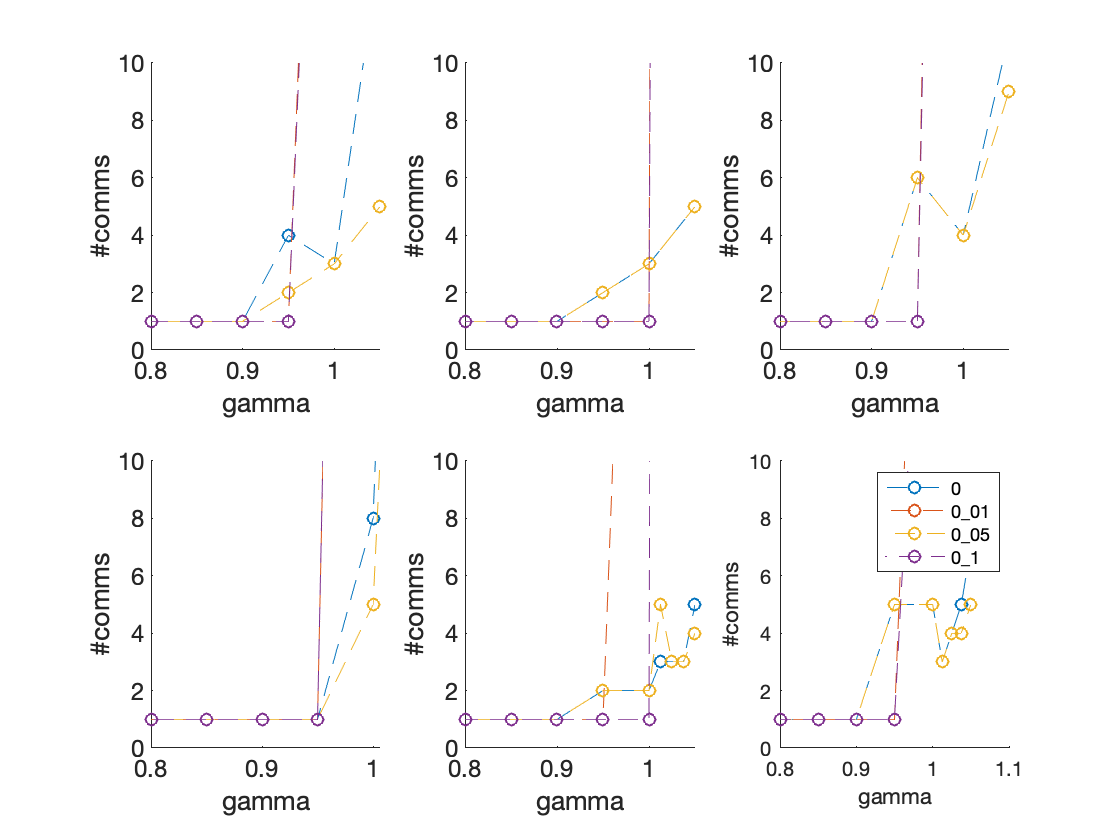

load(sprintf('Data/Robustness/Partitions_0_5'))
 
figure(2); clf;

for i_pt=1:6

p= Partitions((i_pt*2)-1);
inds= find(strcmp(p.ID, {Partitions.ID}));
{Partitions(inds).beta};
{Partitions(inds).states};
{Partitions(inds).gamma};
    
rns=cell(length(betas),1);


subplot(2,3,i_pt)
hold on; 

for b= 1:length(betas)
    for i=1:size(Partitions(inds(b)).medianQcomms,2)
        s =assignStates(Partitions(inds(b)).medianQcomms(:,i));
        rns{b,1}(i,:)=[Partitions(inds(b)).gamma(i), size(s.stateRuns,2)];
    end
    plot(rns{b,1}(:,1), rns{b,1}(:,2), '--o', 'linewidth', .5)
end

% imagesc(rns)
% caxis([0,10])
% colorbar
% title(sprintf('patient%s-%s', p.ID, p.type))
% xticklabels(string(p.gamma))
% xticks([1:length(p.gamma)])
% yticklabels(betas)
% xlabel('gamma')
% ylabel('betas')
% 

% plot(p.gamma, rns)

xlabel('gamma')
ylabel('#comms')
ylim([0,10])

end


legend(betaStr, "Interpreter", "none")


figure(2)
subplot(2,3,1)
imagesc(Network(i_pt).sim)
for i=1:length(betas)
    subplot(2,3,i+1)
    imagesc(Network(1).(['wSim_', betaStr{i}]))
end


## new heading

figure(3)
plot(linspace(1,2,10), sin(linspace(1,2,10)))